# Polígono de Área Máxima

**Proyecto Ⅱ : Solución por puntos interiores.**

**Optimización Numérica**

**ITAM**

Integrantes:

- Luis Felipe Castro Corrales            181417

- Natalia Hernández Cornejo            183420

- Dara Ximena Meneses Acosta       190689

En este proyecto, utilizaremos el método de puntos interiores para obtener el polígono de $n_v$ vértices y de diametro menor o igual a uno de área máxima.

Fijamos el último vértice al origen, es decir $v_n = (0,\pi)$. Así, consideramos $n = n_v-1$ como el número de vértices sin fijar y llegamos a que el problema a minimizar es

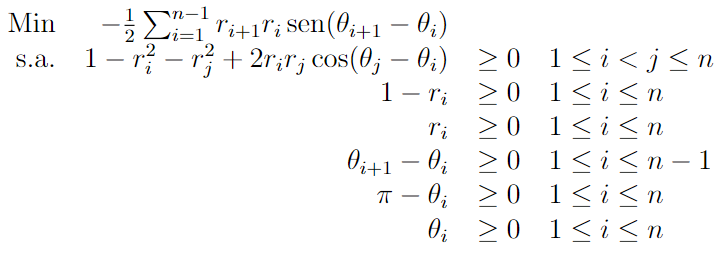

% Ejecutar esta línea para limpiar el espacio de trabajo.
clear; close all; clc;

% n es el números de vértices distintos del origen
hold on
for n = 2:10
    x0 = pInicial(n);
    fname = 'funobj';
    gname = 'funres';
    [x,mu,iter] = intpoint2(fname,gname,x0);
    x;
    
    r = [0 ; x(1:2:2*n-1)];
    theta = [pi; x(2:2:2*n)];
    
    [x,y] = pol2cart(theta,r);
    
    %Graficar polígono
    pgon = polyshape(x,y);
    txt = ['P de ',num2str(n+1),' lados'];
    plot(pgon,'DisplayName',txt)
    
end

 1 2.26455142 0.12657242 
 2 1.11597545 0.53070718 
 3 0.55620264 0.10240733 
 4 0.27759617 0.00311014 
 5 0.18792741 0.00054217 
 6 0.20101422 0.00138268 
 7 0.15420319 0.00001941 
 8 0.11054653 0.00002971 
 9 0.03209409 0.00001928 
10 0.00831722 0.00000004 
11 0.00680376 0.00000001 
12 0.00577918 0.00000000 
13 0.00244076 0.00000000 
14 0.00081480 0.00000000 
15 0.00029132 0.00000000 
16 0.00017338 0.19943390 
17 0.00006529 0.03982557 
18 0.00002554 0.00794410 
19 0.00001121 0.00150794 
20 0.00000529 0.00014857 
 1 3.12423597 0.06525130 
 2 1.50886744 0.04102832 
 3 0.74288228 0.07698004 
 4 0.36850251 0.01206520 
 5 0.21883923 0.00200308 
 6 0.13822520 0.00008367 
 7 0.05629017 0.00000979 
 8 0.02675112 0.00000055 
 9 0.01460695 0.00000003 
10 0.00773631 0.00000000 
11 0.00396985 0.00000000 
12 0.00200095 0.00000000 
13 0.00093862 0.09619933 
14 0.00042000 0.00490143 
15 0.00019291 0.00010686 
16 0.00009372 0.00000140 
17 0.00004687 0.00000001 
18 0.00002352 0.00000000 
19 0.0000117

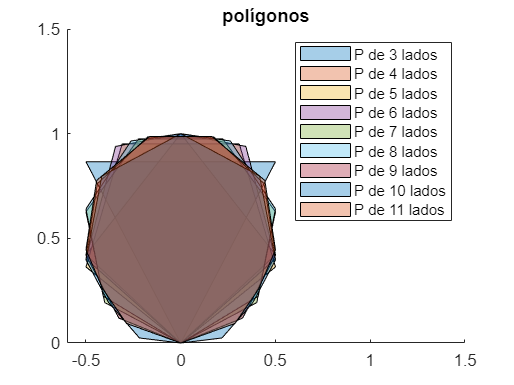

title("Polígonos")
xlim([-0.6 1.5])
ylim([0 1.5])
legend show
hold off